# [IOT/OT Cybersecurity](http://apmonitor.com/pds/index.php/Main/CyberSecurity)

Cybersecurity is the protection of networks and computer systems, including hardware and software, against [cyberattacks](https://en.wikipedia.org/wiki/List_of_cyberattacks). Of particular interest to engineers is the computer control of physical systems that monitor and control transportation, pipelines, water treatment, waste treatment, chemical manufacture, factories, energy production, and other industrial processes. Two areas of cybersecurity focus are:

- Information Technology (IT): computer systems including software, data, and networks

- Operational Technology (OT): devices that control the physical world

OT Cybersecurity is concerned with keeping intruders out of the local control system network and detecting malicious intent from those who have access. Malicious intent may be subtle such as signal manipulation to decrease production, damage equipment, or steal information. One of the first notable cyberattacks was the [Stuxnet virus](https://vimeo.com/25118844) that replayed normal data to the operator to run undetected while damaging equipment over a period of months.

[Machine Learning for Cybersecurity](https://github.com/jivoi/awesome-ml-for-cybersecurity) has many applications that detect phishing, password strength, abnormal network packet flow, intrusions, spam, malware, ransomware, distributed denial of service (DDoS), and other cyberattacks. Most of ML Cybersecurity is focused on [classification](http://apmonitor.com/pds/index.php/Main/ClassificationOverview) to detect bad actors.

Operational Technology (OT) includes computer systems and equipment that make changes to the physical world. Sensors, actuators, and computer control systems are critical to safe operation and are increasingly under threat of attack. Industrial sectors include transportation, manufacturing, energy production, power generation, grid networks, and pipelines. A self-driving car has actuators such as steering direction, motor torque, and brake action. Airplane actuators include engine thrust, aileron angle, and flap position. Industrial chemical process actuators include valves and pumps. It is imperative that the commanded actuator is implemented as requested. There may be a difference between the commanded and actual state of the actuator if there is a cyberattack or equipment malfunction. Cyberattacks may be stealth changes to a process that go undetected but that cause equipment failure, lost economic potential, or HSE (Health, Safety, Environmental) incidents.

## **TCLab**

[IOT/OT Cybersecurity](http://apmonitor.com/pds/index.php/Main/ActuatorMonitor) with the TCLab: Classification to detect when the heater power supply is unplugged or the heater power level is set to zero.

This is a case study with a microcontroller with sensors and actuators ([TCLab](https://apmonitor.com/heat.htm)) where the heater (actuator) is monitored to determine if it is *on* or *off*. The predicted and commanded heater states are compared to determine if there is an equipment failure or external actor that has taken control of the actuator. A TCLab digital twin is included if the hardware is not connected.

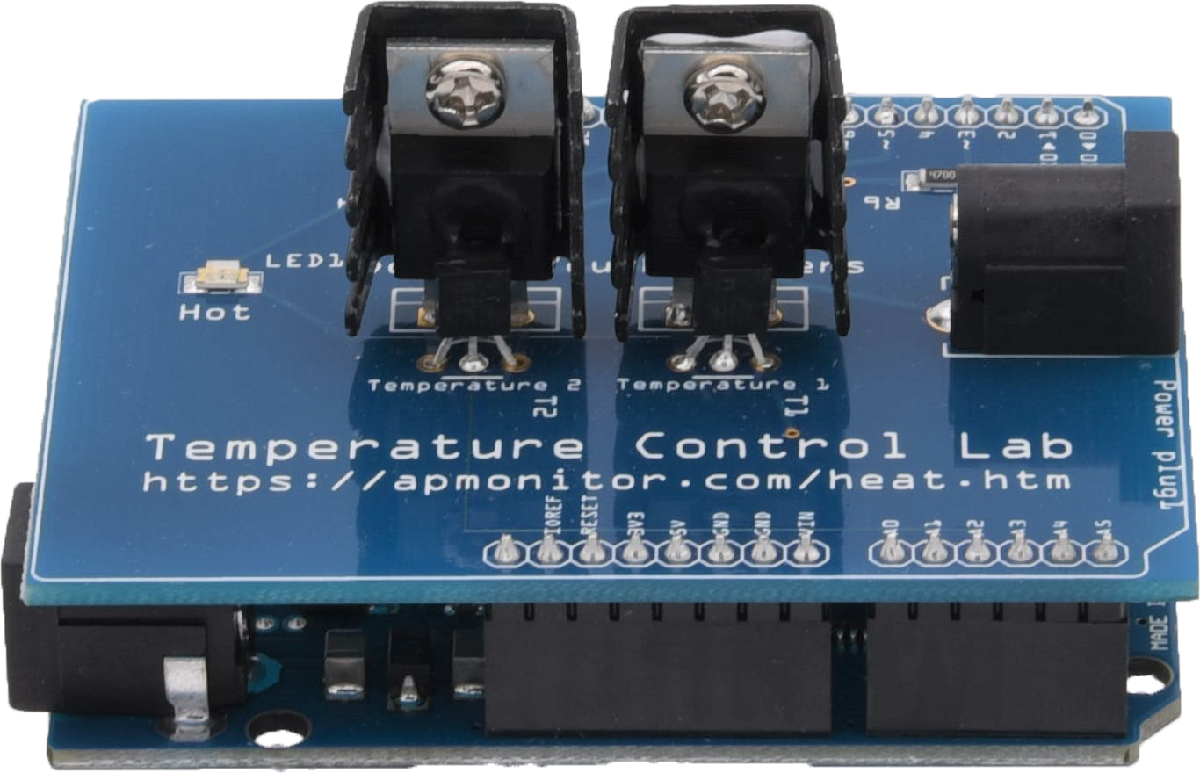

Develop a classifier to predict when the [TCLab heater](https://apmonitor.com/heat.htm) is on and when it is off. Generate labeled data where the heater is either on at 100% output or at 0% output for periods between 10 and 25 seconds.

**TC Data Set**

Small Data Set (10min)

[Sample Data for Testing](http://apmonitor.com/pds/uploads/Main/tclab_data5.txt)

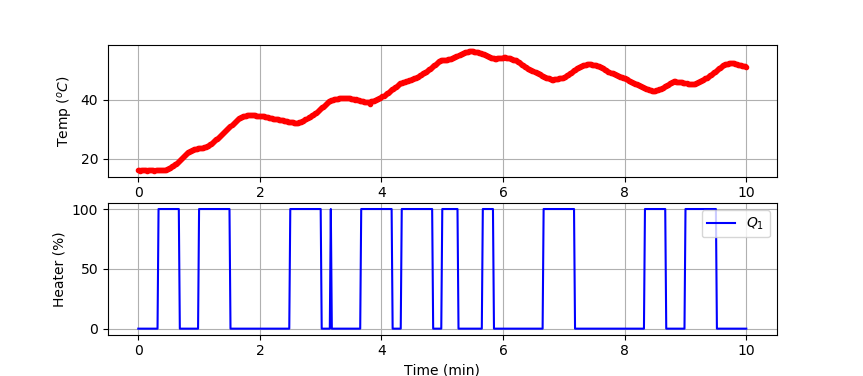

Large Data Set (1hr)

[Sample Data for Training](http://apmonitor.com/pds/uploads/Main/tclab_data6.txt)

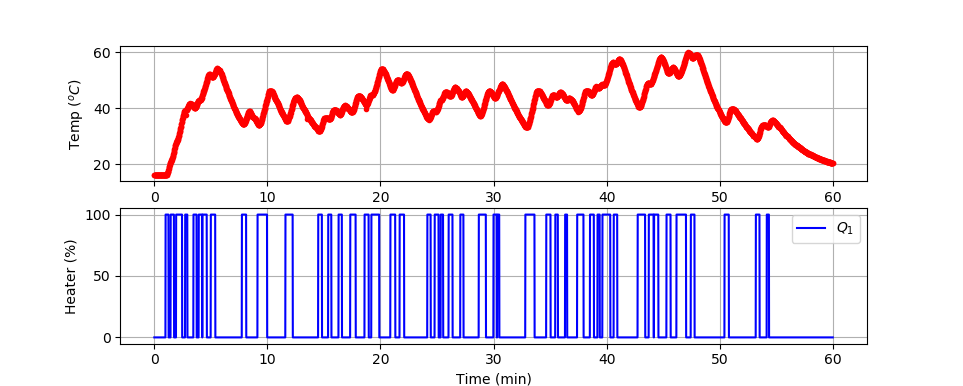

## Classify Data

The [features of the data](http://apmonitor.com/pds/index.php/Main/FeatureEngineering) are selected and scaled (0-1) such as temperature, and temperature derivatives. The measured temperature and derivatives and heater value labels are used to create a classifier that predicts when the heater is on or off. The classifier is validated with new data that was not used for training.

This is a plot of predictions from classifiers previously trained on a 10 minute data set from a TCLab device. 

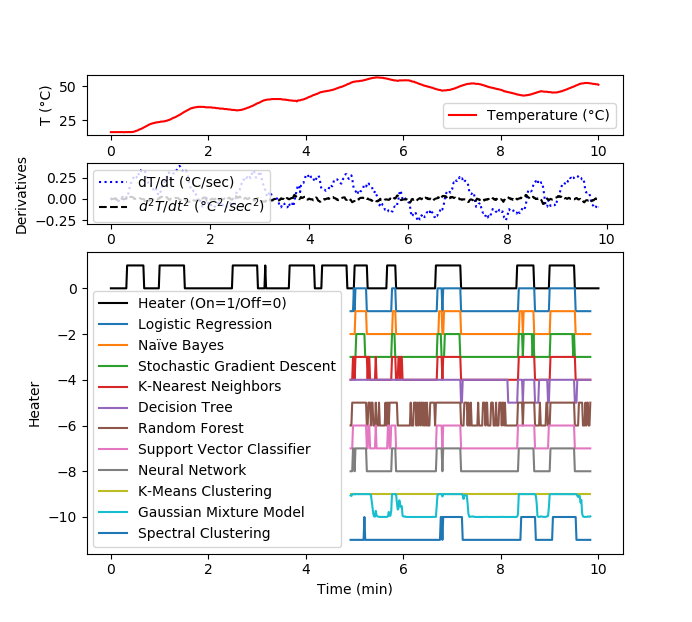

The objective is to create a similar plot of accurate predictions using a 60 minute data set from a TCLab device. 

### **Fit Data**

% Load data
file1 = 'http://apmonitor.com/do/uploads/Main/tclab_data5.txt';
file2 = 'http://apmonitor.com/do/uploads/Main/tclab_data6.txt';
data = readtable(file2);
% Input Features: Temperature and 1st / 2nd Derivatives
% Fit the temperature and heater output data to a cubic polynomial fit.

% Cubic polynomial fit of temperature using 10 data points
data.dT1 = zeros(height(data), 1); % Make an empty array for the first derivative
data.d2T1 = zeros(height(data), 1); % Make an empty array for the second derivative
for i = 1:height(data)
    if i < height(data) - 10
       % Get 10 data points
       x = data.Time(i:i+9) - data.Time(i);
       y = data.T1(i:i+9);
       % Make a cubic polynomial fit
       p = polyfit(x, y, 3);
       % evaluate derivatives at mid-point (5 sec)
       t = 5.0;
       data.dT1(i) = 3.0*p(1)*t^2 + 2.0*p(2)*t + p(3);
       data.d2T1(i) = 6.0*p(1)*t + 2.0*p(2);
    else
       data.dT1(i) = NaN;
       data.d2T1(i) = NaN;
    end
end

% Remove last 10 values
X = table2array(data(:, {'T1', 'dT1', 'd2T1'}));
y = table2array(data(:, 'Q1'));
X(end-9:end, :) = [];
y(end-9:end, :) = [];

% Scale and normalize data
% Input features (Temperature and 2nd derivative at 5 sec)
Xs = normalize(X);

% Output labels (heater On / Off)
ys = double(y > 50);

### **Split Data**

Split the data into test and train subsets for classification.

% Split into train and test subsets (50% each)
splitRatio = 0.5;

numSamples = numel(Xs(:,1));
numTrain = round(splitRatio * numSamples);
numTest = numSamples - numTrain;

% Split the data
Xtrain = Xs(1:numTrain,:);
Xtest = Xs(numTrain+1:end,:);
Ytrain = ys(1:numTrain,:);
Ytest = ys(numTrain+1:end,:);

% Plot regression results code is located at the bottom of the file
Ytrain1 = fillmissing(Ytrain, 'constant', 0);
Xtrain1 = fillmissing(Xtrain, 'constant', 0);
Ytest1 = fillmissing(Ytest, 'constant', 0);
Xtest1 = fillmissing(Xtest, 'constant', 0);

### **Classify**

Classify the data with many different classification methods to compare and contrast the efficacy.

% Supervised Classification

% Multinomial Regression
mr = fitmnr(Xtrain,categorical(Ytrain));
yP1 = mr.predict(Xtest);

% Naïve Bayes
nb = fitcnb(Xtrain, Ytrain);
yP2 = predict(nb, Xtest);

% Stochastic Gradient Descent
sgd = fitclinear(Xtrain1, Ytrain1);
yP3 = predict(sgd, Xtest);

% K-Nearest Neighbors
knn = fitcknn(Xtrain, Ytrain, 'NumNeighbors', 5);
yP4 = predict(knn, Xtest);

% Decision Tree
dtree = fitctree(Xtrain, Ytrain, 'MinLeafSize', 5);
yP5 = predict(dtree, Xtest);

% Random Forest
rfm = TreeBagger(70, Xtrain, Ytrain, 'OOBPrediction', 'On', 'MinLeafSize', 3);
yP6 = str2double(predict(rfm, Xtest));

% Support Vector Classifier
svm = fitcsvm(Xtrain, Ytrain, 'KernelFunction', 'linear');
yP7 = predict(svm, Xtest);

% Neural Network
clf = fitnet([10 30 10]);
clf.divideParam.trainRatio = 0.5;
clf.divideParam.testRatio = 0.5;
clf.trainParam.epochs = 200;
clf.trainParam.lr = 0.01;
clf.trainParam.min_grad = 1e-5;
clf.trainParam.showWindow = false;
clf.trainParam.showCommandLine = false;
clf = train(clf, Xtrain', Ytrain');
yP8 = round(sim(clf, Xtest')');
yP8(yP8 == -1) = 0;

% Unsupervised Classification

% K-Means Clustering
[yP9, km] = kmeans(Xtrain1,2);

% Gaussian Mixture Model
gmm = fitgmdist(Xtrain1,2);
yP10 = gmm.posterior(Xtest1);
yP10 = 1.0 - yP10(:,1);

% Spectral Clustering
yP11 = spectralcluster(Xtest1,2,'Distance','euclidean');

**Interactive Method**

Alternatively you can use the [Classification Learner](https://www.mathworks.com/help/stats/classificationlearner-app.html) app to train models and classify data. Using the app you can explore supervised machine learning using various classifiers. 

### Plot Predictions

Plot the predicted heater output for each classification method.

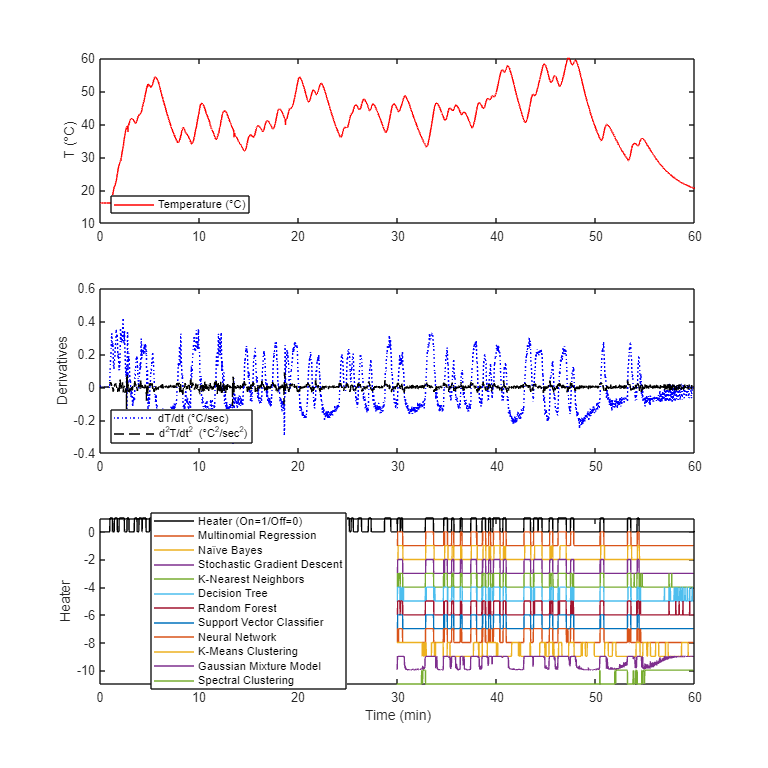

% Create the figure
figure('Units', 'inches', 'Position', [0, 0, 20, 20]);

% Plot the measured temperature vs time
subplot(3,1,1)
plot(data.Time/60, data.T1, 'r-')
ylabel('T (°C)')
legend('Temperature (°C)', 'Location', 'southwest')

% Plot the first and second derivatives
subplot(3,1,2)
plot(data.Time/60, data.dT1, 'b:')
hold on
plot(data.Time/60, data.d2T1, 'k--')
ylabel('Derivatives')
legend('dT/dt (°C/sec)', 'd^2T/dt^2 (°C^2/sec^2)','Location', 'southwest')

% Plot the real heater setting and then each prediction
subplot(3,1,3)
plot(data.Time/60, data.Q1/100, 'k-' )
hold on
t2 = data.Time(numel(Ytrain)+1:end-10); % Make a time array from 30 minutes to the end
plot(t2/60, double(yP1)-2)
plot(t2/60, yP2-2)
plot(t2/60, yP3-3)
plot(t2/60, yP4-4)
plot(t2/60, yP5-5)
plot(t2/60, yP6-6)
plot(t2/60, yP7-7)
plot(t2/60, yP8-8)
plot(t2/60, yP9(1:end-1)-10)
plot(t2/60, yP10-10)
plot(t2/60, yP11-12)
ylabel('Heater')
xlabel('Time (min)')
legend('Heater (On=1/Off=0)','Multinomial Regression','Naïve Bayes', 'Stochastic Gradient Descent', 'K-Nearest Neighbors','Decision Tree', ...
    'Random Forest','Support Vector Classifier','Neural Network','K-Means Clustering','Gaussian Mixture Model','Spectral Clustering', 'Location', 'best')

#### Analysis

Above we can see the measured temperature, the first and second derivatives of temperature, when the heater was on or off, and the eleven classifier predictions. Overall the eight supervised learning classifiers performed very well, with just a few mistakes in K-Nearest Neighbors, Decision Tree, and Random Forest. The unsupervised learning classifiers did not perform as well, with many innacurate predictions throughout the entire thirty minutes. Unsupervised learning means that the classifier is not given the target labels before hand. It's objective is to classify the data based on inherent patterns, structures, or relationships. In this example, supervised learning worked much better. 